## Atomic Force Microscopy

### 1. Importing the force curves

Make a copy of the main.mlx live script and the src directory and paste it to the directory where the force curve files are. The first step assumes that the force curves files are in the same directory as this script. 

This will create the standard directory layout:

`./raw: `Where the jpk-force files are

`./incoming: `Where the relevant channels will be extracted to.

`./processed: `Where the shift-scaled force curves will be safed

And extract  a *filename*_approach.mat and a *filename_*retract.mat matrix, in which the first column is the respective sensor height and the second column the deflection.

Remember to correctly set the path after opening this script.

 
clear;
fullScriptPath = matlab.desktop.editor.getActiveFilename;
[script_dir, ~, ~] = fileparts(fullScriptPath);
% Change directory to the live script's directory
cd(script_dir);
addpath('./src/')

path_incoming = './incoming/';
path_processed = './processed/';
path_raw = './raw/';
if exist('./raw/',"dir")
    force_dir = dir(fullfile(path_raw,'*.jpk-force'));
else
    force_dir = dir(fullfile(script_dir,'*.jpk-force'));
end

 
if ~exist(path_incoming,"dir")
    mkdir(path_incoming)
end
if ~exist(path_processed,"dir")
    mkdir(path_processed)
end
if ~exist(path_raw,"dir")
    mkdir(path_raw)
end

force_dir = dir(fullfile(script_dir,'*.jpk-force'));
for i = 1:length(force_dir)
    base_str = force_dir(i).name;
    src_file = fullfile(script_dir, base_str);
    dest_file = fullfile(path_raw, base_str);
    
    try
        copyfile(src_file, dest_file);
        if exist(dest_file, 'file') == 2
            delete(src_file);
        else
            error('File copy failed: %s', base_str);
        end
    catch ME
        fprintf('Error occurred: %s. File was not deleted: %s\n', ME.message, base_str);
    end
end

force_dir = dir(fullfile(path_raw,'*.jpk-force'));
for i = 1:length(force_dir)
    base_str =force_dir(i).name;
    extract(path_raw,path_incoming,base_str,2);
end

### 2. Rescaling the force curves

The force curves need to be rescaled in order to get physical units. Two linear fits are to be made to achieve this. One for constant compliance and one for the baseline regions. First the respective intervals need to be chosen to get the best fit for all curves. 

Plot a few example force curves to chose the interval where the baseline and constant compliance is linear.

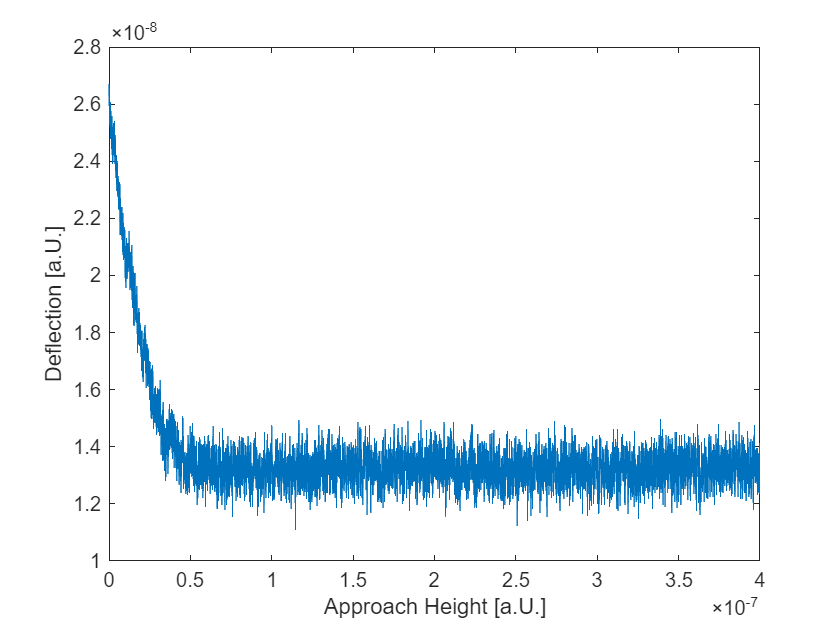

 
cd(script_dir);
curve_id =  1;
base_str = force_dir(curve_id).name;
load(fullfile(path_incoming,[base_str,'_approach.mat']))
plot(height,deflection)
xlabel('Approach Height [a.U.]');
ylabel('Deflection [a.U.]');

% Improved MATLAB code to load all approach and retract curves, overlay them, and save as PNG

% Directory containing your data files (replace with the correct path)

% Create a new figure
figure;

% Hold on to overlay all curves on the same figure
hold on;
% Loop through each curve_id in the directory
for curve_id = 1:length(force_dir)
    
    % Base string from the filename (assuming filenames are consistent)
    base_str = force_dir(curve_id).name;
    
    approach_file = fullfile(path_incoming, [base_str, '_approach.mat']);
    load(approach_file)
    plot(approach_height,approach_deflection, Color='blue')

    retract_file = fullfile(path_incoming, [base_str, '_retract.mat']);
    load(retract_file)
    plot(retract_height,retract_deflection, Color='red')
end

% Add labels and title
xlabel('Height [a.U.]');
ylabel('Deflection [a.U.]');
title('Overlayed Approach and Retract Force Curves');

% Customize the grid and axis
grid on;
axis tight;

% Save the figure as a PNG image
saveas(gcf, 'all_curves_overlay.png');

% Close the figure (optional)
close(gcf);


Then chose the Interval of constant compliance and of the baseline.  The distribution of the Sum of Squared Errors of the fits will be shown. *Should be gaussian and as low as possible?*. 

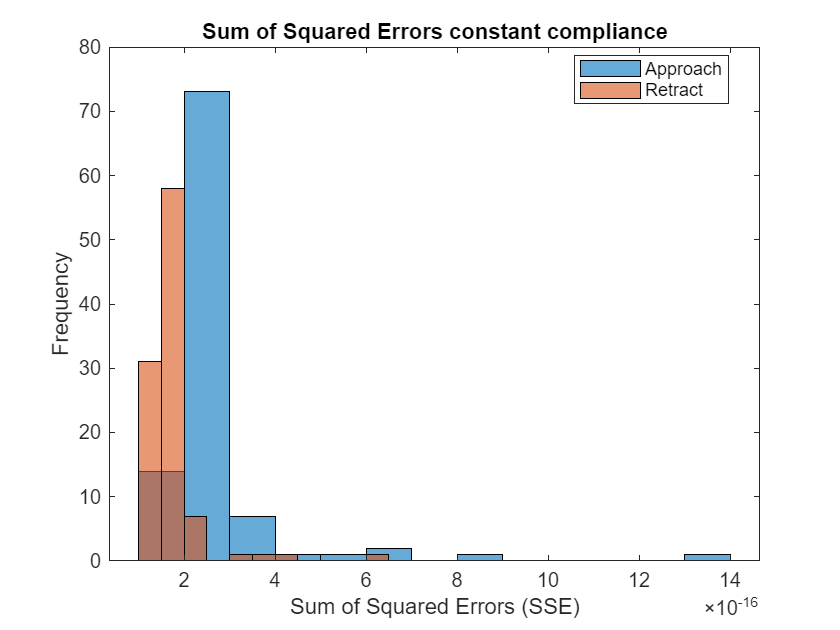

 
cd(script_dir)
%const_compliance_min = 0;
const_compliance_max = 1.65e-8;
baseline_min = 1.034e-7;
baseline_max = 4e-7;

n = length(force_dir);
SSEc = zeros(1, n);
mc = zeros(1, n);
bc = zeros(1, n);
SSE = zeros(1, n);
m = zeros(1, n);
b = zeros(1, n);

r_SSEc = zeros(1, n);
r_mc = zeros(1, n);
r_bc = zeros(1, n);
r_SSE = zeros(1, n);
r_m = zeros(1, n);
r_b = zeros(1, n);

for i =1:length(force_dir)
    base_str = force_dir(i).name;
    [SSEc(i),mc(i),bc(i), SSE(i), m(i), b(i)] = fitforce(path_incoming,[base_str,'_approach.mat'], const_compliance_max,baseline_min);%approach
    [r_SSEc(i),r_mc(i),r_bc(i), r_SSE(i), r_m(i), r_b(i)] = fitforce(path_incoming,[base_str,'_retract.mat'], const_compliance_max,baseline_min);%retract
end
figure;
histogram(SSEc, 'DisplayName', 'Approach')
hold on; 
histogram(r_SSEc, 'DisplayName', 'Retract')
xlabel('Sum of Squared Errors (SSE)'); 
ylabel('Frequency'); 
title('Sum of Squared Errors constant compliance');
legend('Location', 'best');
hold off;

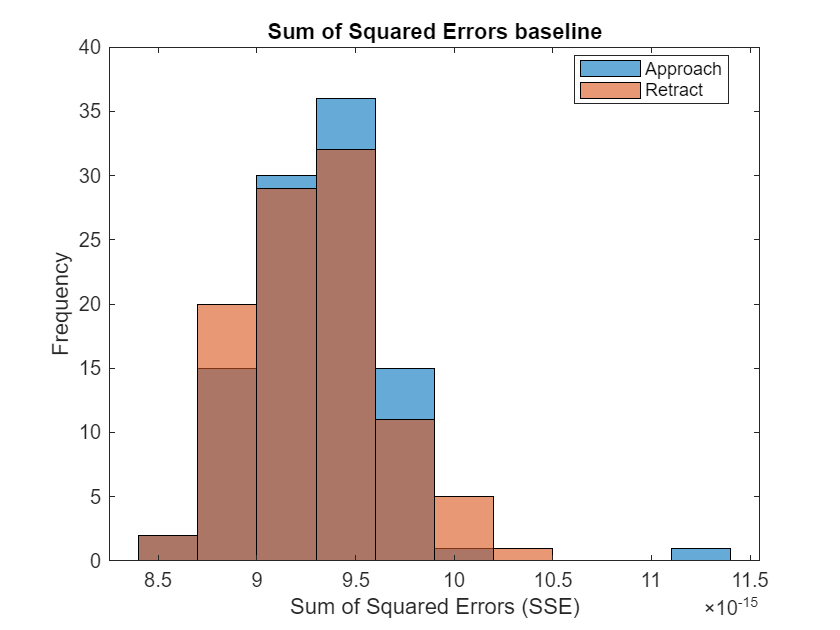


figure;
histogram(SSE,'DisplayName', 'Approach')
hold on;
histogram(r_SSE,'DisplayName', 'Retract');
xlabel('Sum of Squared Errors (SSE)');
ylabel('Frequency'); 
title('Sum of Squared Errors baseline');
legend('Location', 'best');
hold off;

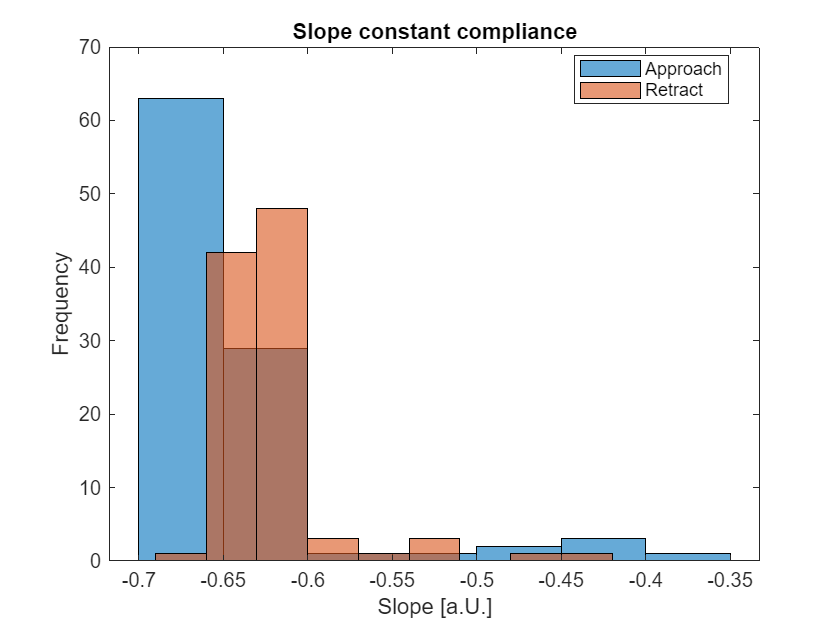

figure;
histogram(mc,'DisplayName', 'Approach')
hold on;
histogram(r_mc,'DisplayName', 'Retract')
xlabel('Slope [a.U.]');
ylabel('Frequency'); 
title('Slope constant compliance');
legend('Location', 'best');
hold off;

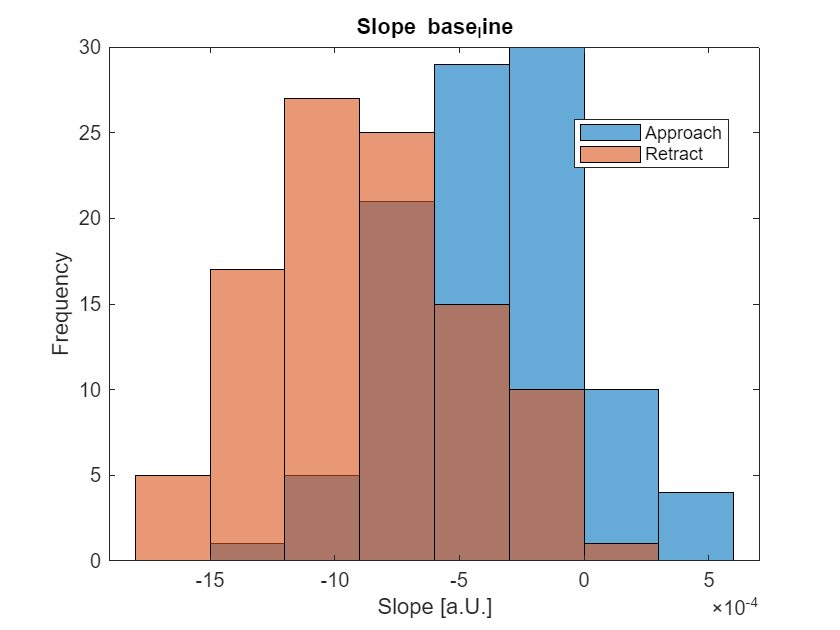

figure;
histogram(m,'DisplayName', 'Approach')
hold on; 
histogram(r_m,'DisplayName', 'Retract')
xlabel('Slope [a.U.]');
ylabel('Frequency'); 
title('Slope base_line');
legend('Location', 'best');
hold off;

You can again inspect the force curves with their fits.

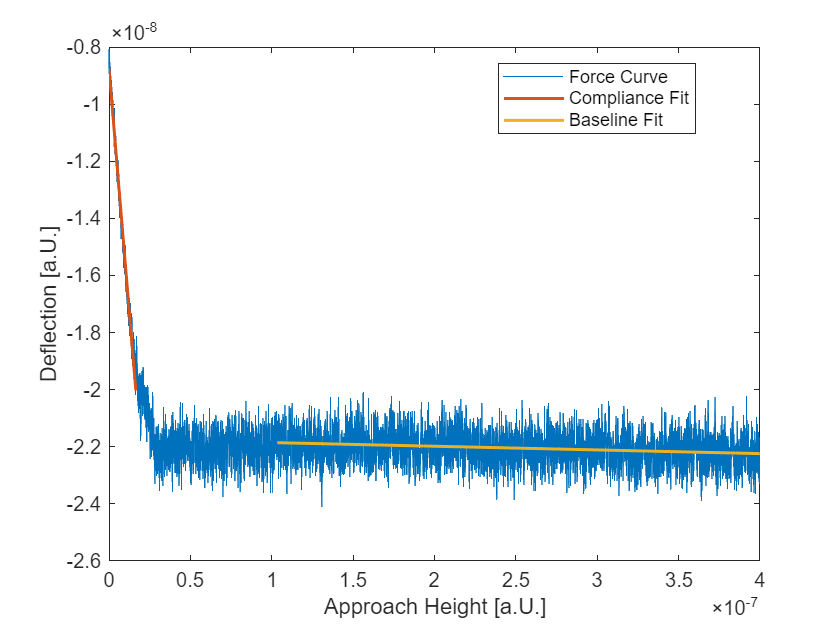

 
cd(script_dir);
curve_id =  99;
base_str = force_dir(curve_id).name;
approach=load(fullfile(path_incoming,[base_str,'_approach.mat']),'height','deflection');
retract=load(fullfile(path_incoming,[base_str,'_retract.mat']));
plot(approach.height,approach.deflection)
xlabel('Approach Height [a.U.]');
ylabel('Deflection [a.U.]');

hold on;

% Define the first line: left-most approach height to constant_compliance_max
x1 = linspace(0, const_compliance_max, 100); % Define the range
y1 = mc(curve_id) * x1 + bc(curve_id); % Calculate the y-values
plot(x1, y1, 'LineWidth', 1.5); % Plot with a dashed red line

% Define the second line: baseline_min to baseline_max
x2 = linspace(baseline_min, max(approach.height), 100); % Define the range
y2 = m(curve_id) * x2 + b(curve_id); % Calculate the y-values
plot(x2, y2, 'LineWidth', 1.5); % Plot with a dashed green line

% Add labels
xlabel('Approach Height [a.U.]');
ylabel('Deflection [a.U.]');

% Add a legend for clarity
legend('Force Curve', 'Compliance Fit', 'Baseline Fit', 'Location', 'Best');

hold off;

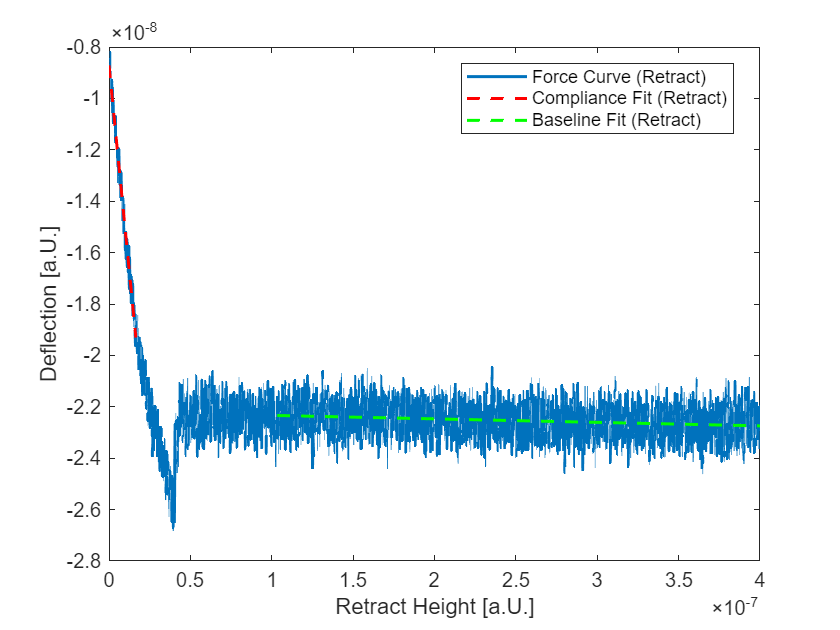

% Second figure: Retract data and fits
figure;
plot(retract.height, retract.deflection, 'LineWidth', 1.5); % Plot the retract data
xlabel('Retract Height [a.U.]');
ylabel('Deflection [a.U.]');
hold on;

% Compliance Fit for retract
x1_retract = linspace(0, const_compliance_max, 100); % Range
y1_retract = r_mc(curve_id) * x1_retract + r_bc(curve_id); % Compliance fit for retract
plot(x1_retract, y1_retract, '--r', 'LineWidth', 1.5); % Dashed red line for retract compliance

% Baseline Fit for retract
x2_retract = linspace(baseline_min, max(retract.height), 100); % Range
y2_retract = r_m(curve_id) * x2_retract + r_b(curve_id); % Baseline fit for retract
plot(x2_retract, y2_retract, '--g', 'LineWidth', 1.5); % Dashed green line for retract baseline

% Legend and finishing touches
legend('Force Curve (Retract)', 'Compliance Fit (Retract)', 'Baseline Fit (Retract)', 'Location', 'Best');
hold off;

Now the force curves will be rescaled to get physical units.

 
cd(script_dir);
baseline_min_shifted = zeros(length(force_dir),1);
baseline_max_shifted = zeros(length(force_dir),1);
for i =1:length(force_dir)
    base_str = force_dir(i).name;
    rescale(path_incoming, path_processed, base_str, mc(i),bc(i),m(i),b(i), r_mc(i),r_bc(i),r_m(i),r_b(i))
    baseline_min_shifted(i) =baseline_min + (-bc(i)+ b(i))/(mc(i)-m(i));
    baseline_max_shifted(i) =baseline_max + (-bc(i)+ b(i))/(mc(i)-m(i));
end


You can plot a few scaled example curves. 

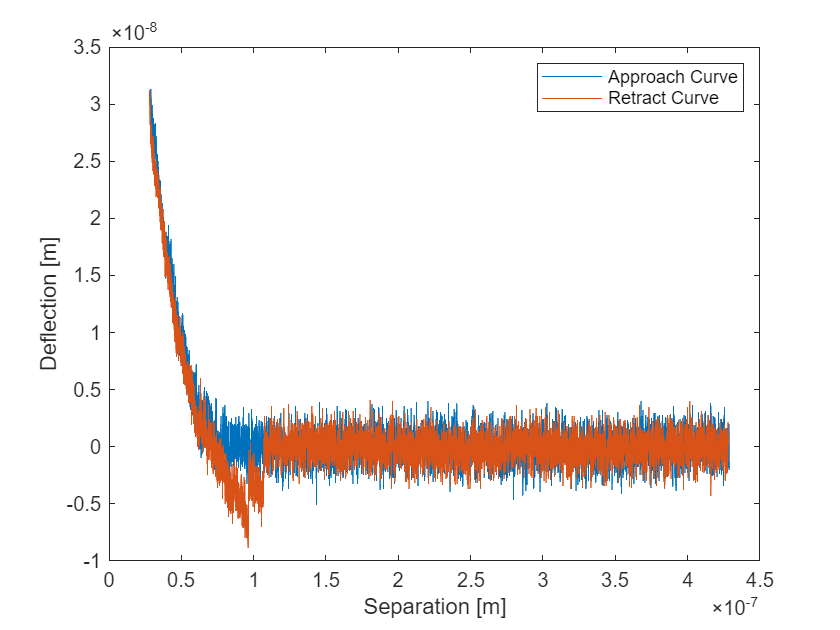

 
cd(script_dir);
curve_id =  1;
base_str = force_dir(curve_id).name;
approach = load(fullfile(path_processed,[base_str,'_approach_scaled.mat']));
retract = load(fullfile(path_processed,[base_str,'_retract_scaled.mat']));

% Plot the approach curve
plot(approach.shifted_height, approach.scaled_deflection, 'DisplayName', 'Approach Curve');
hold on;
% Plot the retract curve
plot(retract.shifted_height, retract.scaled_deflection, 'DisplayName', 'Retract Curve');
% Add labels
xlabel('Separation [m]');
ylabel('Deflection [m]');
% Add a legend
legend('show'); % Automatically uses the 'DisplayName' properties of the plots
hold off;

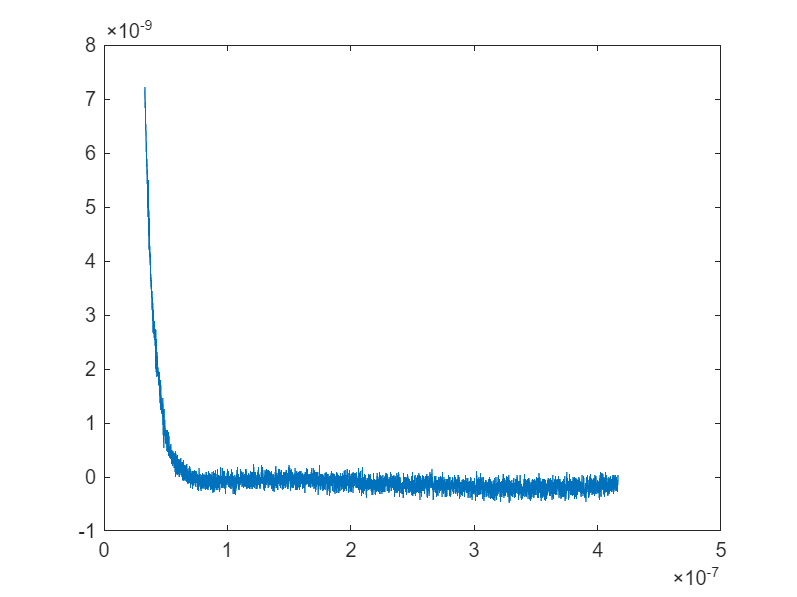

% Loading files


% Initialize variables
num_spectra = length(force_dir);
min_num_points = inf;  % Initialize to a large number

% First, loop through the files to find the common frequency range and the min number of points
for i = 1:num_spectra
    approach = load(fullfile(path_processed, [force_dir(i).name, '_approach_scaled.mat']));

    % Update the common frequency range (min and max across all files)
    if i == 1
        freq_min = min(approach.shifted_height);
        freq_max = max(approach.shifted_height);
    else
        freq_min = max(freq_min, min(approach.shifted_height));
        freq_max = min(freq_max, max(approach.shifted_height));
    end

    % Find the number of valid points within the common range
    valid_indices = find(approach.shifted_height >= freq_min & approach.shifted_height<= freq_max);
    num_valid_points = length(valid_indices);
    
    % Track the minimum number of valid points across all spectra
    min_num_points = min(min_num_points, num_valid_points);
end

% Calculate bin width based on the minimum number of data points
frequency_range = freq_max - freq_min;
bin_width = frequency_range / min_num_points;  % Dynamic bin width based on min number of points

% Define the common frequency bins based on the bin width
common_height = freq_min:bin_width:freq_max;

% Initialize accumulated power
accumulated_deflection = zeros(length(common_height), 1);

% Loop through each spectrum and bin the power
for i = 1:num_spectra
    approach = load(fullfile(path_processed, [force_dir(i).name,'_approach_scaled.mat']));

    % Find the indices of frequencies that are within the common frequency range
    valid_indices = find(approach.shifted_height >= freq_min & approach.shifted_height <= freq_max);
    
    % Extract the valid frequencies and corresponding power spectrum values
    valid_height = approach.shifted_height(valid_indices);
    valid_deflection= approach.scaled_deflection(valid_indices);

    % Bin the power spectrum
    [~, bin_indices] = histc(valid_height, common_height);  % Get bin indices
    
    % Accumulate power in the corresponding bins
    for k = 1:length(valid_height)
        if bin_indices(k) > 0 && bin_indices(k) <= length(accumulated_deflection)
            accumulated_deflection(bin_indices(k)) = accumulated_deflection(bin_indices(k)) + valid_deflection(k);
        end
    end
end

% Compute the mean binned spectrum
mean_deflection = accumulated_deflection / num_spectra;

% Plot the result
plot(common_height, mean_deflection);  % Exclude last bin edge for plot

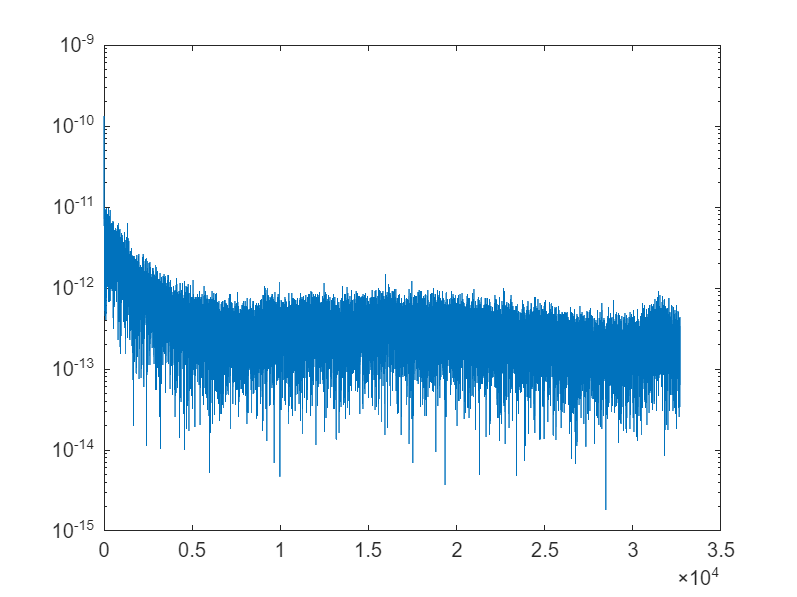

 velocity = 5e-7;
 baseline_min = 1e-7;
 baseline_max = 4e-7;
% Time vector from height and velocity
    height_time = common_height ./ velocity;
    baseline_min_time = baseline_min / velocity;
    baseline_max_time = baseline_max / velocity;
    
    % Apply baseline mask
    mask = (height_time >= baseline_min_time) & (height_time <= baseline_max_time);
    force_curve = mean_deflection(mask);
    
    % Compute the FFT of the force curve
     % Compute the power spectrum (positive frequencies, excluding DC component)
    L = length(force_curve); % Number of points
    % Frequency vector 
    sampling_interval = abs(mean(diff(height_time(mask)))); % Approximate sampling interval
    Fs = 1 / sampling_interval; % Sampling frequency

    Y = fft(force_curve);
    P2 = abs(Y/L);
    P1 = P2(1:floor(L/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    frequencies = Fs/L*(0:(L/2));
    semilogy(frequencies, P1)

### 3. Measuring the cantilever spring constant

Now the spring constant of the cantilever will be estimated using a Fourier Transformation of the baseline vibrations. Enter the approach velocity in m/s to convert the approach height to units of time.

 
velocity = 5e-7;
cd(script_dir);
for i =1:length(force_dir)
    base_str = force_dir(i).name;
    Copy_of_powerspec(path_processed,base_str,velocity,baseline_min_shifted(i),baseline_max_shifted(i))
end


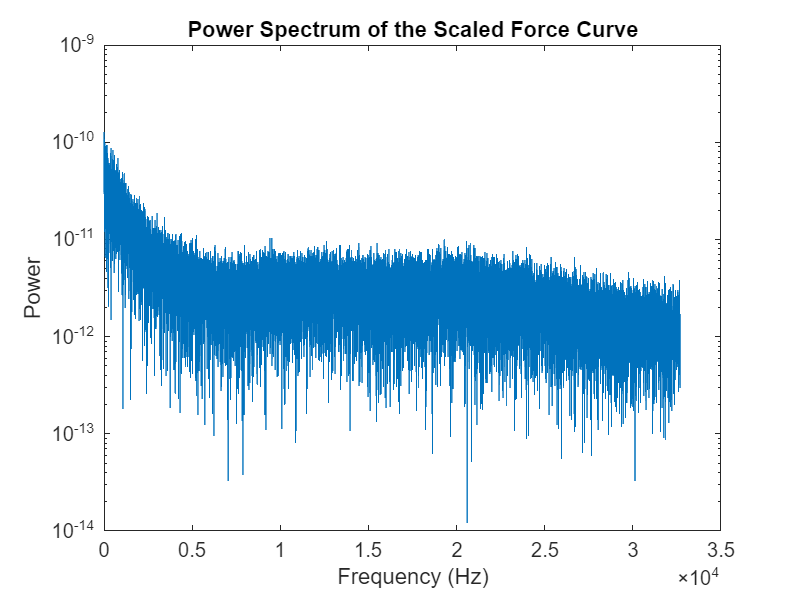

 
cd(script_dir)
curve_id =  35;
base_str = force_dir(curve_id).name;
load(fullfile(path_processed,[base_str,'_power_spectrum.mat']))
% Plot the power spectrum
figure;
semilogy(frequencies, power_spectrum);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Power Spectrum of the Scaled Force Curve');

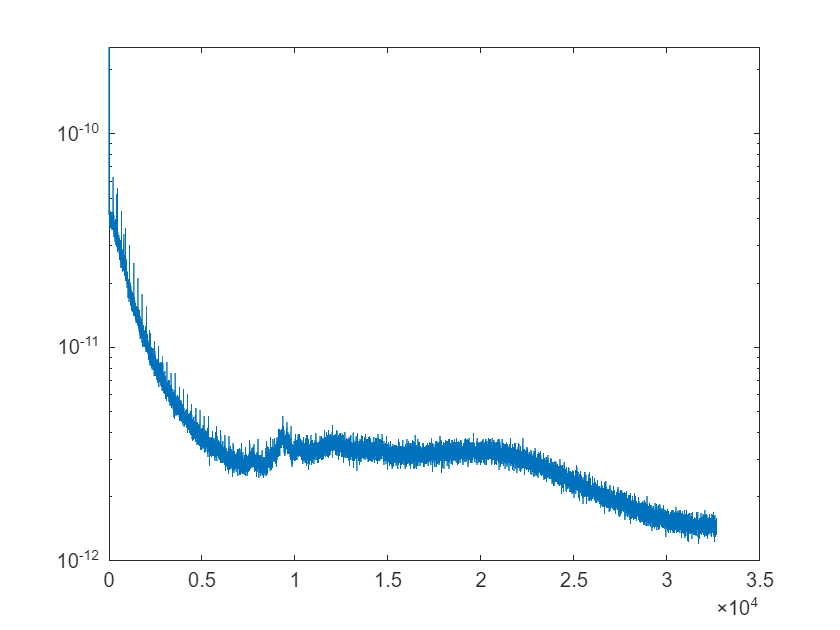

% Loading files
files = dir(fullfile(path_processed, '*power_spectrum.mat'));

% Initialize variables
num_spectra = length(files);
min_num_points = inf;  % Initialize to a large number

% First, loop through the files to find the common frequency range and the min number of points
for i = 1:num_spectra
    data = load(fullfile(path_processed, files(i).name));
    power_spectrum = data.power_spectrum;
    frequencies = data.frequencies;

    % Update the common frequency range (min and max across all files)
    if i == 1
        freq_min = min(frequencies);
        freq_max = max(frequencies);
    else
        freq_min = max(freq_min, min(frequencies));
        freq_max = min(freq_max, max(frequencies));
    end

    % Find the number of valid points within the common range
    valid_indices = find(frequencies >= freq_min & frequencies <= freq_max);
    num_valid_points = length(valid_indices);
    
    % Track the minimum number of valid points across all spectra
    min_num_points = min(min_num_points, num_valid_points);
end

% Calculate bin width based on the minimum number of data points
frequency_range = freq_max - freq_min;
bin_width = frequency_range / min_num_points;  % Dynamic bin width based on min number of points

% Define the common frequency bins based on the bin width
common_frequencies = freq_min:bin_width:freq_max;

% Initialize accumulated power
accumulated_power = zeros(length(common_frequencies)-1, 1);

% Loop through each spectrum and bin the power
for i = 1:num_spectra
    data = load(fullfile(path_processed, files(i).name));
    power_spectrum = data.power_spectrum;
    frequencies = data.frequencies;

    % Find the indices of frequencies that are within the common frequency range
    valid_indices = find(frequencies >= freq_min & frequencies <= freq_max);
    
    % Extract the valid frequencies and corresponding power spectrum values
    valid_frequencies = frequencies(valid_indices);
    valid_power_spectrum = power_spectrum(valid_indices);

    % Bin the power spectrum
    [~, bin_indices] = histc(valid_frequencies, common_frequencies);  % Get bin indices
    
    % Accumulate power in the corresponding bins
    for k = 1:length(valid_frequencies)
        if bin_indices(k) > 0 && bin_indices(k) <= length(accumulated_power)
            accumulated_power(bin_indices(k)) = accumulated_power(bin_indices(k)) + valid_power_spectrum(k);
        end
    end
end

% Compute the mean binned spectrum
mean_binned_spectrum = accumulated_power / num_spectra;

% Plot the result
semilogy(common_frequencies(1:end-1), mean_binned_spectrum);  % Exclude last bin edge for plot
saveas(gcf,"./thermal_noise_spectrum.png")